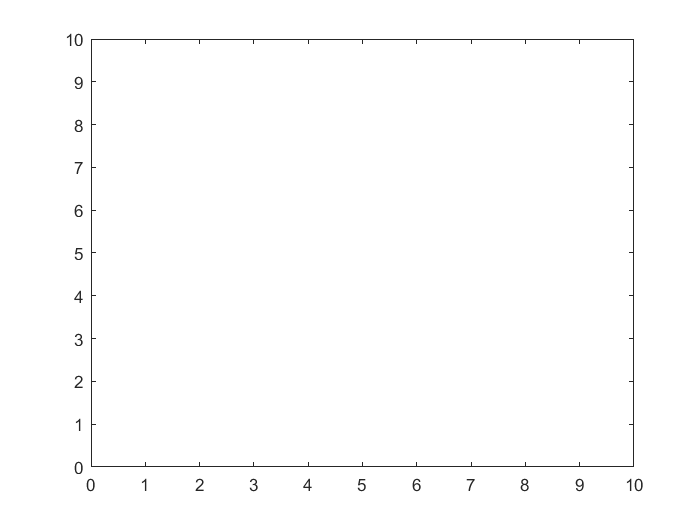

% Set the starting coordinates and velocity
x0 = 5; % starting x-coordinate
y0 = 10; % starting y-coordinate
v = 0.5; % velocity in the y-direction

% Define the x-coordinate as a constant
x = x0*ones(100,1); % create an array of x-coordinates

% Set the time limit for showing the circle
tlimit = 5; % time limit in seconds

% Set the start time
tstart = tic; % start the timer

% Simulate the motion of the circle
for t = 1:100
    y(t) = y0 - v*t; % calculate the y-coordinate at time t
    if toc(tstart) >= tlimit % check if the time limit has been reached
        break; % exit the loop if the time limit has been reached
    end
    plot(x(t),y(t),'ro','MarkerSize',10,'LineWidth',2); % plot the circle at time t with larger size and thicker edge
    xlim([0 10]); % set the x-axis limits
    ylim([0 10]); % set the y-axis limits
    pause(0.1); % pause for 0.1 seconds before plotting the next circle
end